a=1+mod(964,3)

a = 2

Q1

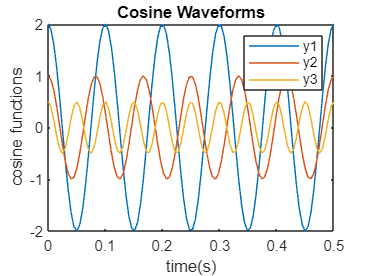

t=linspace(0,1/a);
y1=a*cos(2*pi*5*a*t);
y2=(a/2)*cos(2*pi*6*a*t);
y3=(a/4)*cos(2*pi*10*a*t);

figure;plot(t,y1,t,y2,t,y3)
xlabel('time(s)')
ylabel("cosine functions");
title("Cosine Waveforms")
legend('y1','y2','y3')

Q2

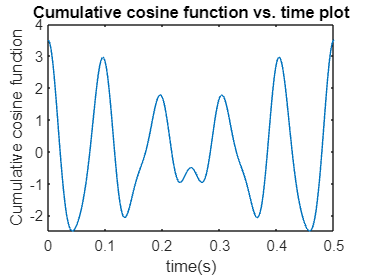

y4=y1+y2+y3;
figure;plot(t,y4)
xlabel('time(s)')
ylabel('Cumulative cosine function')
title('Cumulative cosine function vs. time plot')

Q3

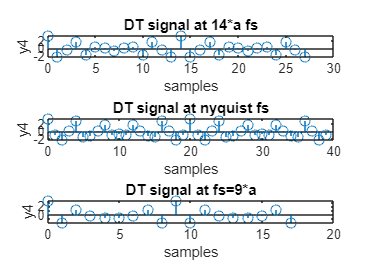

subplot(3,1,1)
a=2;
fs1=14*a;
n1=0:fs1-1;
t1=1/fs1;
y4=a*cos(2*pi*5*a*n1*t1)+(a/2)*cos(2*pi*6*a*n1*t1)+(a/4)*cos(2*pi*10*a*n1*t1);
stem(n1,y4)

xlabel('samples')
ylabel('y4')
title('DT signal at 14*a fs')

subplot(3,1,2)
fs2=2*10*a;
t2=1/fs2;
n2=0:fs2-1;
y42=a*cos(2*pi*5*a*n2*t2)+(a/2)*cos(2*pi*6*a*n2*t2)+(a/4)*cos(2*pi*10*a*n2*t2);
stem(n2,y42)

xlabel('samples')
ylabel('y4')
title('DT signal at nyquist fs')

subplot(3,1,3)
fs3=9*a;
t3=1/fs3;
n3=0:fs3-1;
y43=a*cos(2*pi*5*a*n3*t3)+(a/2)*cos(2*pi*6*a*n3*t3)+(a/4)*cos(2*pi*10*a*n3*t3);
stem(n3,y43)
xlabel('samples')
ylabel('y4')
title('DT signal at fs=9*a')

Q4

figure;
t=[0:1/fs1:a]

t =          0    0.0357    0.0714    0.1071    0.1429    0.1786    0.2143    0.2500    0.2857    0.3214    0.3571    0.3929    0.4286    0.4643    0.5000    0.5357    0.5714    0.6071    0.6429    0.6786    0.7143    0.7500    0.7857    0.8214    0.8571    0.8929    0.9286    0.9643    1.0000    1.0357    1.0714    1.1071    1.1429    1.1786    1.2143    1.2500    1.2857    1.3214    1.3571    1.3929    1.4286    1.4643    1.5000    1.5357    1.5714    1.6071    1.6429    1.6786    1.7143    1.7500


plot(t,y4)

Error using plot
Vectors must be the same length.

ylabel('Interpolation at 28 Hz frequency')
xlabel('time(s)')

plot(t,y42)
xlabel('time(s)')
ylabel('Interpolation at 40 Hz frequency')

plot(t,y43)
xlabel('time(s)')
ylabel('Interpolation at 18 Hz frequency')


Q5

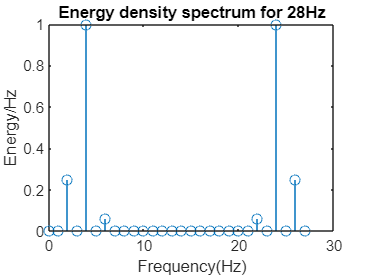

y1=fft(y4); 
z1=fftshift(y1);
ly1=length(y1);
f_vec1=(0:ly1-1)*fs1/ly1;
amplitude_spectrum1=abs(z1)/fs1;
figure;stem(f_vec1,abs(amplitude_spectrum1).^2);
xlabel('Frequency(Hz)')
ylabel('Energy/Hz')
title('Energy density spectrum for 28Hz')

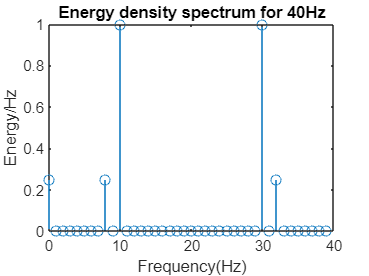


y2=fft(y42); 
z2=fftshift(y2);
ly2=length(y42);
f_vec2=(0:ly2-1)*fs2/ly2;
amplitude_spectrum2=abs(z2)/fs2;
figure;stem(f_vec2,abs(amplitude_spectrum2).^2);
xlabel('Frequency(Hz)')
ylabel('Energy/Hz')
title('Energy density spectrum for 40Hz')

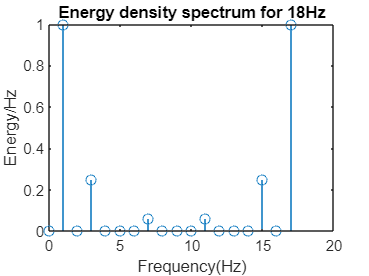


y3=fft(y43); 
z3=fftshift(y3);
ly3=length(y43);
f_vec3=(0:ly3-1)*fs3/ly3;
amplitude_spectrum3=abs(z3)/fs3;
figure;stem(f_vec3,abs(amplitude_spectrum3).^2);
xlabel('Frequency(Hz)')
ylabel('Energy/Hz')
title('Energy density spectrum for 18Hz')

Q6

time_resolution = 0.001;
samples = 5000;
t = 0:0.1*time_resolution:(samples-1)* time_resolution;
do=sin(2*pi*261.63*t);
re=sin(2*pi*293.66*t);
mi=sin(2*pi*329.63*t);
fa=sin(2*pi*349.23*t);
so=sin(2*pi*392*t);
la=sin(2*pi*440*t);
ti=sin(2*pi*493.88*t);

notes=[do re mi fa so la ti];
fs=44100;
filename='notes.wav';
audiowrite(filename,notes,fs);
%sound(notes,fs);
subplot(3,1,1)
plot(notes)
xlim([0 500])
title('Original musical notes')
subplot(3,1,2)
f1=fs/2;
[num,den]=rat(f1/fs);
notes1=resample(notes,num,den);
% sound(notes1,f1)
audiowrite('notes1.wav',notes1,fs)

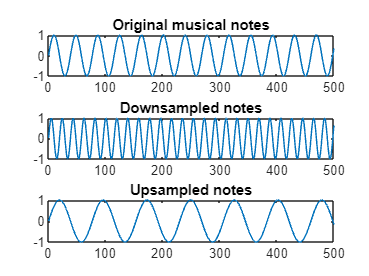

plot(notes1)
title("Downsampled notes")
xlim([0 500])
subplot(3,1,3)
f2=2*fs;
[num,den]=rat(f2/fs);
notes2=resample(notes,num,den);
plot(notes2)
xlim([0 500])
title("Upsampled notes")

Q7

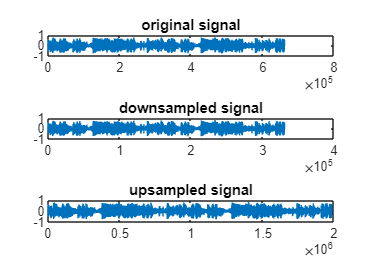

[s,fs]=audioread("Track002.wav");
f1=fs/2;
[num,den]=rat(f1/fs);
s1=resample(s,num,den);
%sound(s,fs)
%sound(s1,f1);
subplot(3,1,1)
plot(s)
title('original signal')
subplot(3,1,2)
plot(s1)

title('downsampled signal')
subplot(3,1,3)
f2=3*fs;
[num,den]=rat(f2/fs);
s3=resample(s,num,den);
plot(s3)
title('upsampled signal')
